## Open Loop Controller Comparison

clear;
controllers = ["PI","PIR","MS","Mod","ILR"];

### Simulation

simout = sim("resonance_step");
u = simout.logsout.find("u").Values;
y = simout.logsout.find("y").Values;

### Frequency Responses

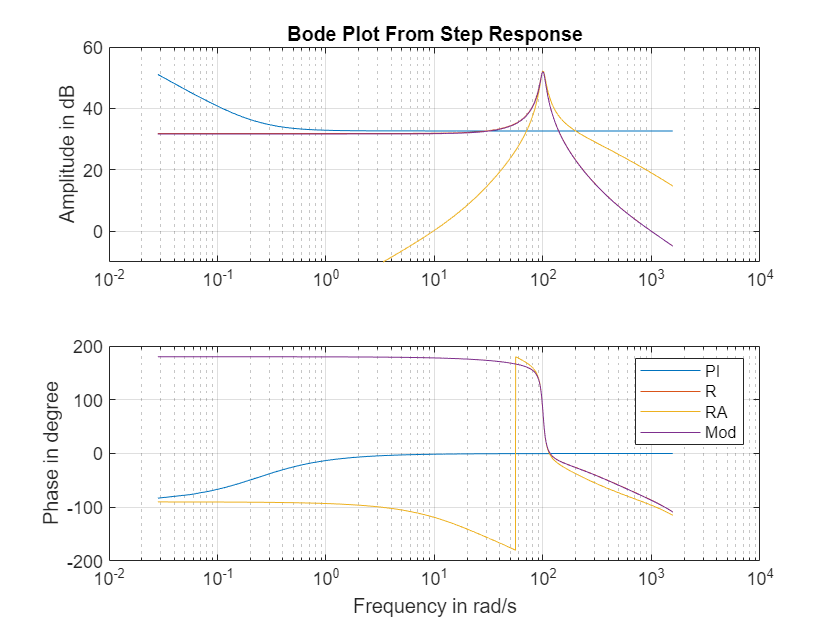

[u,y,w,G] = mybode("resonance_pulse2");
legend("PI","R","RA","Mod");
subplot(2,1,1)
ylim([-10 60])

[u,y,w,G] = mybode("resonance_pulse3");

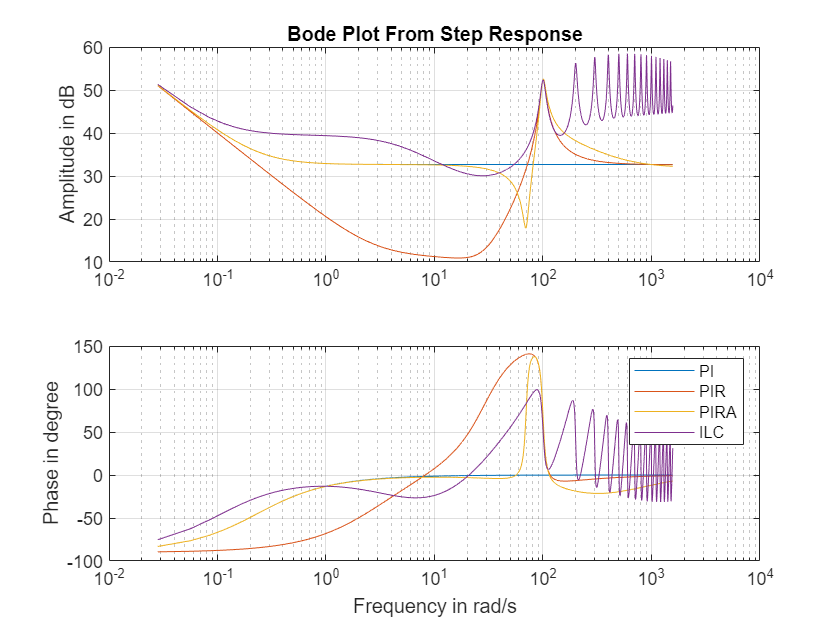

legend("PI","PIR","PIRA","ILC");

[u,y,w,G] = mybode("resonance_pulse4");

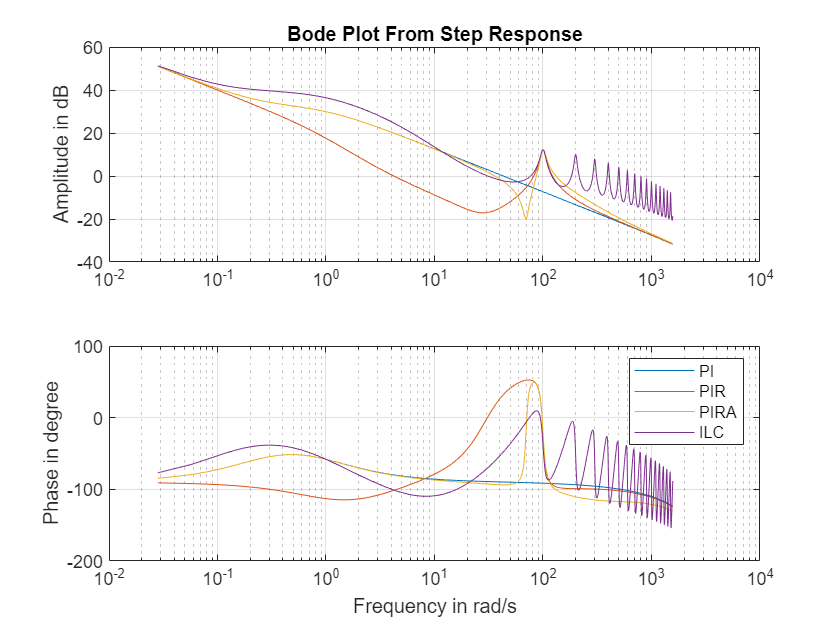

legend("PI","PIR","PIRA","ILC");

[u,y,w,G] = mybode("resonance_pulse5");

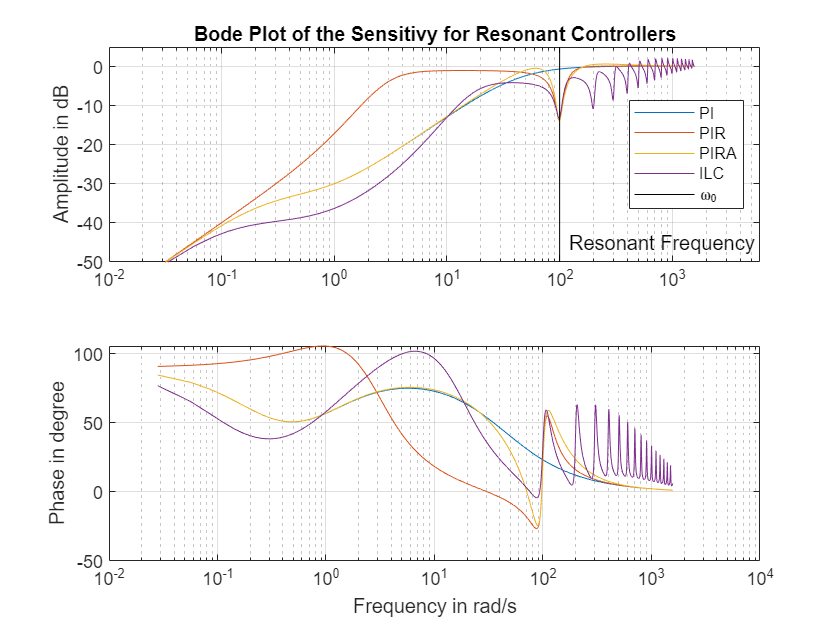

title("Bode Plot of the Sensitivy for Resonant Controllers");
hold on;
plot([100 100],[-50 5],'k');
axis([1e-2 6e3 -50 5]);
text(120,-45,"Resonant Frequency");
legend("PI","PIR","PIRA","ILC","\omega_0","Location","East");
hold off;

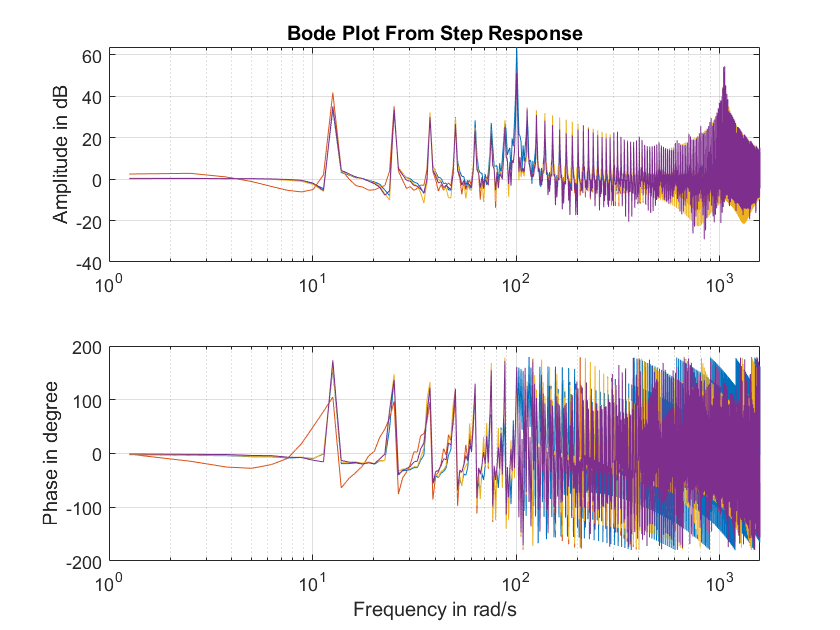

% Ignore the figure, it is not reliably because of the control input
[u,y,w,G] = mybode("resonance_loop2");

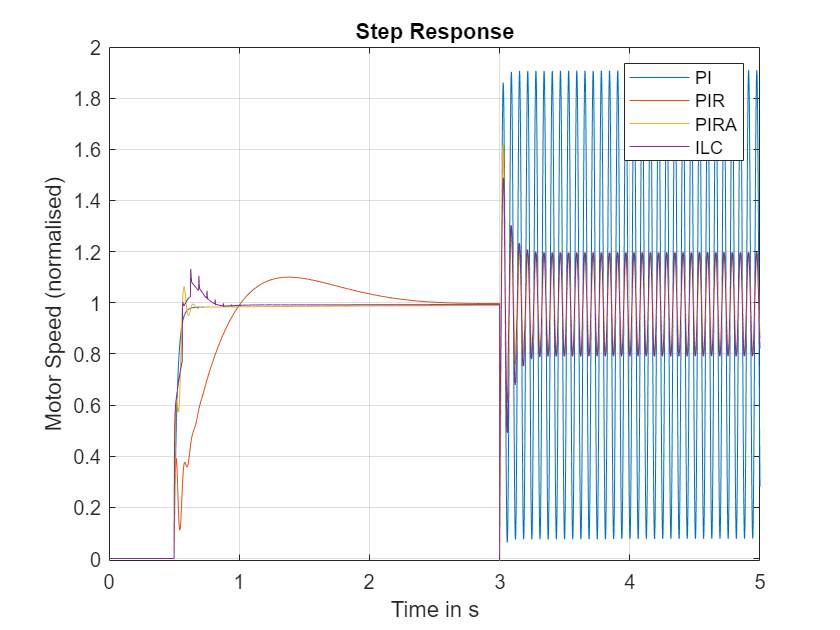

figure;
plot(y);
title("Step Response");
xlabel("Time in s");
ylabel("Motor Speed (normalised)");
legend("PI","PIR","PIRA","ILC");
grid;

### Bode Plot 2

function [u,y,f,G]=mybode(name)
    simout = sim(name);
    u = simout.logsout.find("u").Values;
    y = simout.logsout.find("y").Values;
     
    G=[];
    for n=1:size(y.Data,2)
        F=fft(squeeze(y.Data(:,n,:)))./fft(u.Data);
        G=[G;(F(1:round(length(F)/4)))'];
    end
    f=((0:length(G)-1))/u.Time(end);
    w=2*pi*f;
    
    figure;
    subplot(2,1,1);
    semilogx(w,mag2db(abs(G)));
    title("Bode Plot From Step Response");
    ylabel('Amplitude in dB');
    grid;
    subplot(2,1,2);
    semilogx(w,-rad2deg(angle(G)));
    ylabel('Phase in degree');
    xlabel('Frequency in rad/s');
    grid;

    subplot(2,1,1);
end